Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128


p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));

pn = [p1n p2n p3n p4n]';
tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
%net0.inputs{1}.processFcns   = {'removeconstantrows'};
%net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,p,t2);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    24



disp('Which has MSE =')

Which has MSE =


disp(M0)

   3.2720e+03



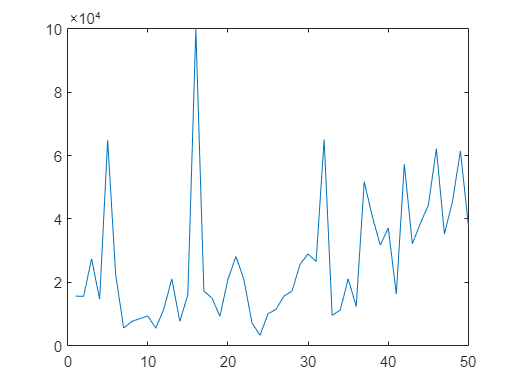

hold off;

net1 = fitnet(13,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 13
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
%net1.inputs{1}.processFcns   = {'removeconstantrows'};
%net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'poslin';

[net1,tr1] = train(net1,p,t2);

output_ANN1 = s_ipf_tansig(p)

output_ANN1 =   117.9777  118.0435  117.9825  120.4436  120.4688  120.4557  122.0151  122.0844  122.1058  138.9789  139.7714  140.4375  140.7766  140.8441  140.7972  142.6894  142.6879  142.6834  162.1517  162.2094  162.1052  162.4890  162.4753  162.3559  163.6289  163.1823  162.8031  169.8251  169.8236  169.8404   84.5975   84.4989   84.5284   84.1007   82.7327   81.4289   97.4762   97.3232   97.4823   96.8742   96.9196   97.2704   97.2940   97.2266   97.3183  110.4053  110.4684  110.3924  109.9410  110.1164


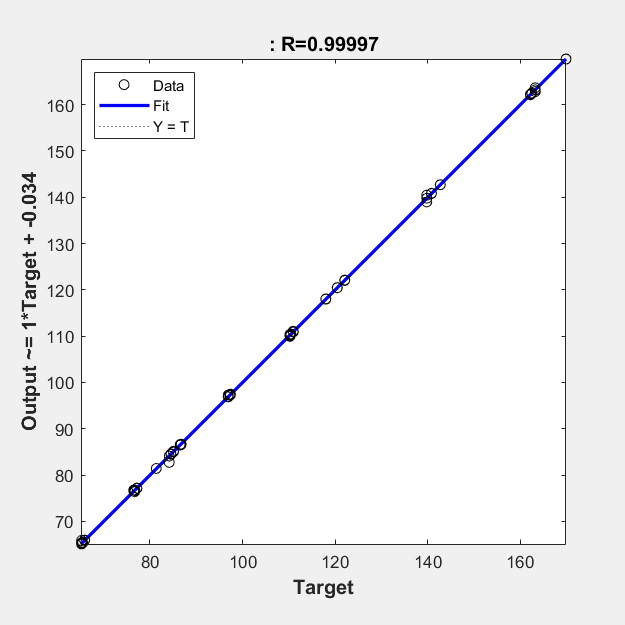

%ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))
%ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))
%plotregression(t1,ANNIPF)
%plotregression(t2,ANNSEA)
plotregression(t1,output_ANN1);

pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.7033
    0.4865



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 138.7970

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.4532e+03